这段code显示纳米颗粒散射的方向性

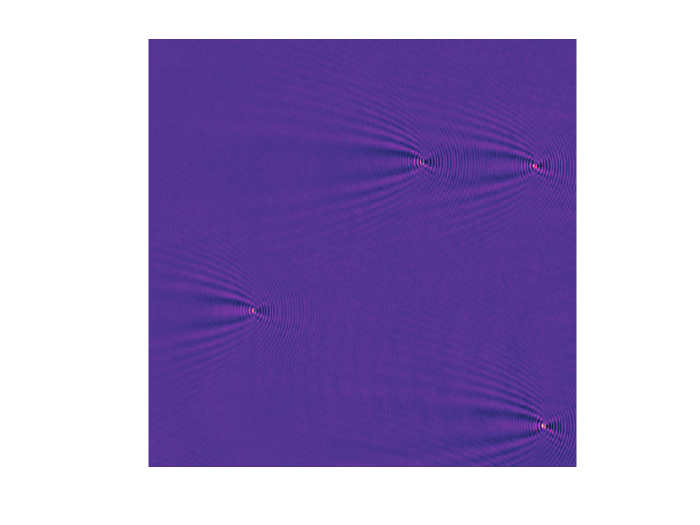

clear all
clc
tiffpath = 'D:\work\散射场\实验数据\20220407_AuNPs_AgNWs\AuNPs_60nm\A1';
% tiffpath = 'D:\work\散射场\实验数据\20220408_PsNPs_colission\PsNPs_300nm\BG';
tiffs = dir(fullfile(tiffpath,'*.tiff'));

BG = MVMExtBG(tiffpath);

I = double(imread(fullfile(tiffpath,tiffs(3).name))) - BG;
% I = imcrop(I);
I = I(1:480,1:480);

figure
imagesc(I);
axis off
axis equal
colormap(sunglow)

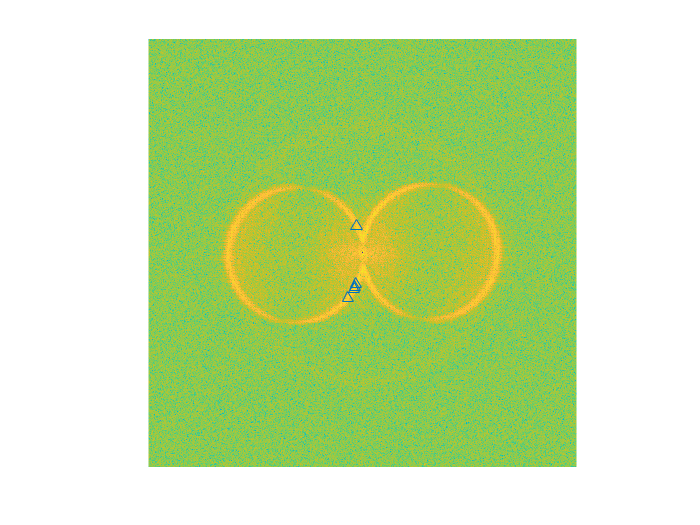

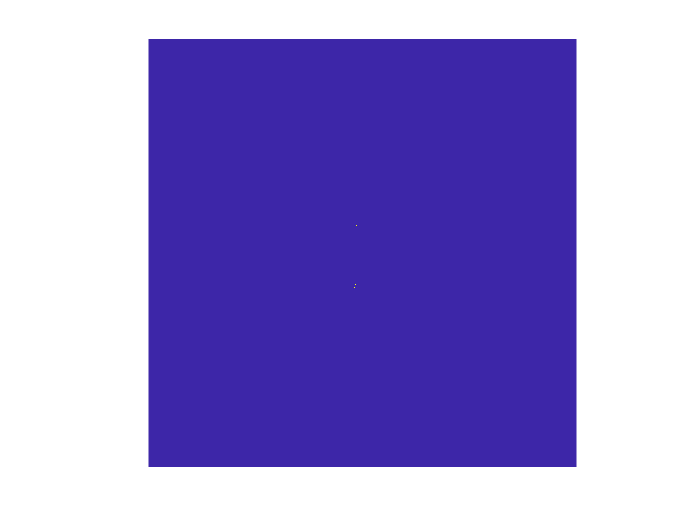

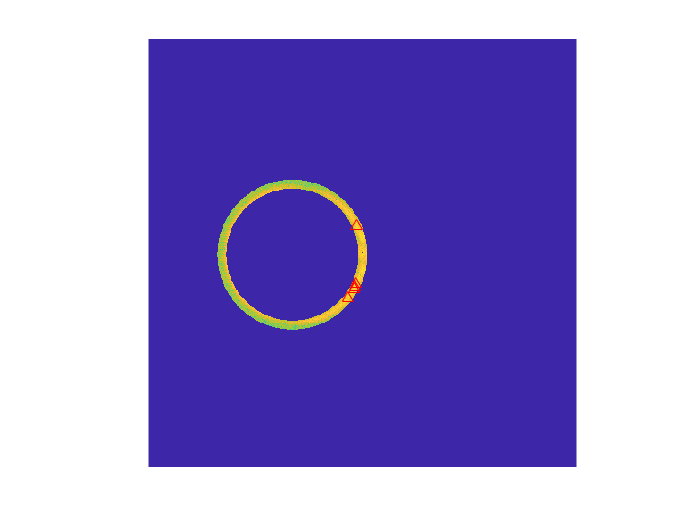


F = fftshift(fft2(I));
[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,1);

peaks = [center_col,center_raw,R];
mask = EwaldMask(F,peaks,0.15,'G',2);
I_rcn = (ifft2(ifftshift(F.*mask)));

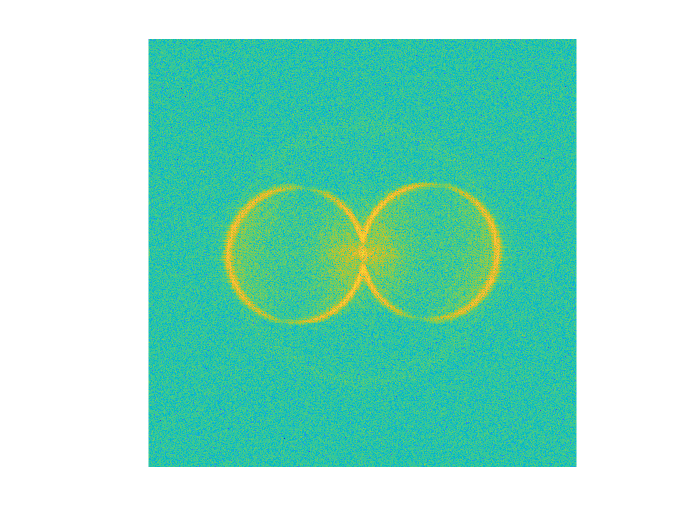

[I_,angleMask] = RadiationIntensity(F,peaks,0.2,36);
figure
imagesc(log(abs(F)))
axis off
axis square

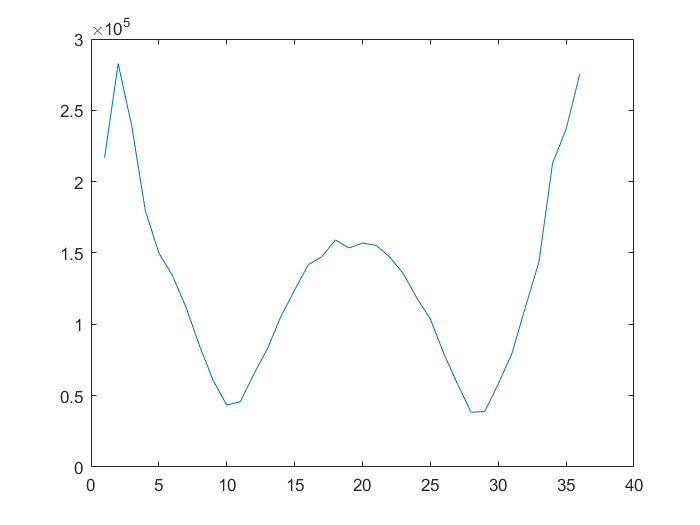

figure
plot(abs(I_))

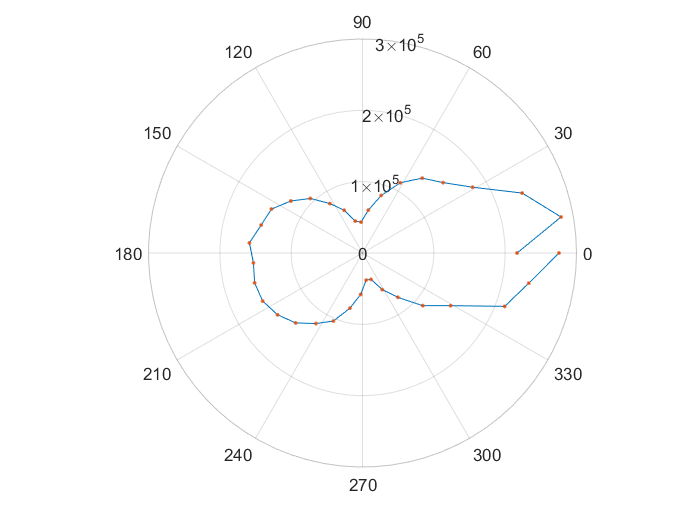

theta = linspace(0,2*pi,36);
figure
polarplot(theta,I_,'-')
hold on
polarplot(theta,I_,'.')